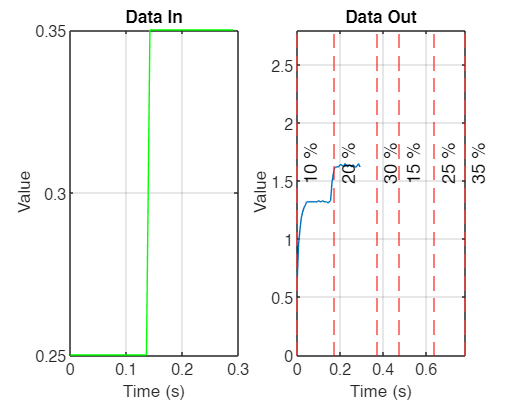

clc
clear all
close all
L = 36.5e-6; % 36.5e-6 % 4.531487031093688e-05
C = 100e-6; % 100e-6 &ì% 1.105016093182359e-04
R = 12; % 12 %7.244561067432775
M = 2.33; % Coupling 2.33
k = 0.99;
load("bm9_cut.mat")

t=data_in(:,1);
subplot(1,2,1)
plot(t, data_in(:,2),'Color','green');
xlabel('Time (s)');
ylabel('Value');
title('Data In');
grid on;


subplot(1,2,2)
plot(t, data_out(:,2));
xlabel('Time (s)');
ylim([0,2.8])
ylabel('Value');
title('Data Out');
grid on;

% Add vertical lines with text labels
hold on;
for i = 1:numel(x_values)
    xline(x_values(i), 'r--');  % Add vertical line at x-value
    text(x_values(i), max(data_out(:,2)), text_labels{i}, 'VerticalAlignment', 'cap', 'HorizontalAlignment', 'center','Rotation', 90);
end
hold off;


t = 0:dt:47*dt;

data_in(:,1) = t;
data_out(:,1) = t;